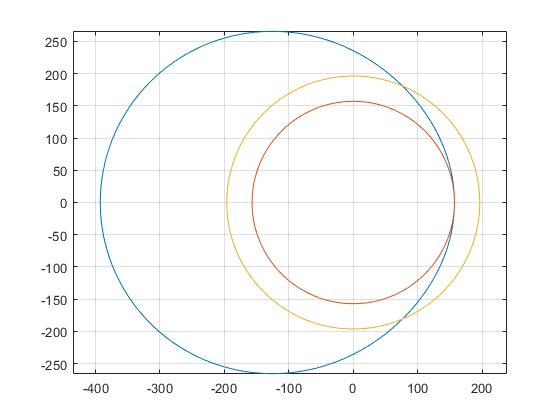

%ALL DIMENSIONS IN mm
a = 200;
b = 300;
s = 200;
m = a/b;
%inner radius= a; outer radius=b
%angle= theta
thetaMax = cosh(1-(m+1)^2/2);

theta=0*pi:pi/100:2*pi;
alpha = 0*pi:pi/100:2*pi;
r = sqrt((a+b)^2 - (b*sin(theta)).^2) - b.*cos(theta);
instantaneousContact = (pi/8).*(r+s);
plot(instantaneousContact.*cos(theta), instantaneousContact.*sin(theta)); hold on;
plot((pi/8)*(a+s).*cos(-alpha), (pi/8)*(a+s).*sin(-alpha)); hold on;
plot((pi/8)*(b+s).*cos(-alpha), (pi/8)*(b+s).*sin(-alpha)); hold on;
%plot(-instantaneousContact.*cos(theta), instantaneousContact.*sin(theta)); hold on;

axis equal
grid on